clearvars
%Ignore the codes below
% =========================================================================
% DEFINE KWAVEARRAY
% =========================================================================

% create empty array
% karray = kWaveArray
% % define arc properties
% radius    = 30e-3;              % [mm]
% diameter  = 30e-3;              % [mm]
% focus_pos = [-2.5e-3, 0];        % [mm]
% 
% % add arc shaped element
% elem_pos  = [-37.5e-3, 0];    % [m]
% karray.addArcElement(elem_pos, radius, diameter, focus_pos);


% move the array down 10 mm, and rotate by 10 degrees (this moves all the
% elements together)
%karray.setArrayPosition([10e-3, 0], 10);




% %define the grid
% Nx = 80;%600
% Ny = 80;%450
% dx = 1e-3;%2e-4
% dy = 1e-3;%2e-4
% Kgrid = kWaveGrid(Nx,dx,Ny,dy);
% c = 1500;
% alpha = 0.75%alpha absorption coefficient
% 
% 
% %define the medium prperty
% medium.sound_speed = 1500;
% medium.alpha_coeff = 0.75;
% medium.alpha_power = 1.5;
% 
% % create the time array explicitly
% Kgrid.t_array = 0:1e-8:8e-5;
% %Kgrid.makeTime(medium.sound_speed,0.3,8e-5);%128SQRT2/1500
% t_array_new = Kgrid.t_array(1:101)
% 
% % assign binary mask from karray to the source mask
% source.p_mask = karray.getArrayBinaryMask(Kgrid)
% 
% % define a time varying sinusoidal source
% source_freq = 1e6;   % [Hz]
% source_mag = 3;         % [Pa]
% %source_signal = source_mag * sin(2 * pi * source_freq * t_array_new);
% source_signal = 1
% % get distributed source signals (this automatically returns a weighted
% % source signal for each grid point that forms part of the source)
% source.p = karray.getDistributedSourceSignal(Kgrid, source_signal);
% 
% % define a single source point
% % source.p_mask = zeros(Nx, Ny);
% % source.p_mask(Nx/2, Ny/2) = 1;
% 
% 
% %% 
% 
% % filter the source to remove high frequencies not supported by the grid
% % source.p = filterTimeSeries(Kgrid, medium, source.p);
% 
% %define the sensor in a line
% x_offset = 2 % [grid points]
% width = 60% [grid points]
% sensor.mask = zeros(Nx, Ny);
% sensor.mask(x_offset, Ny/2 - width/2:1:Ny/2 + width/2) = 1

% run the simulation
%kspaceFirstOrder2D(Kgrid, medium, source, []);
% sensor_data = kspaceFirstOrder2D(Kgrid, medium, source, sensor);



% create pml mask (default size in 2D is 20 grid points)
% pml_size = 20;
% pml_mask = false(Nx, Ny);
% pml_mask(1:pml_size, :) = 1;
% pml_mask(:, 1:pml_size) = 1;
% pml_mask(end - pml_size + 1:end, :) = 1;
% pml_mask(:, end - pml_size + 1:end) = 1;
% 
% % plot source and pml masks
% figure;
% imagesc(Kgrid.y_vec, Kgrid.x_vec, source.p_mask | pml_mask);
% axis image;
% colormap(flipud(gray));
% 
% % overlay the physical source positions
% hold on;
% karray.plotArray(false);

clearvars
%define the grid
Nx = 600;%600
Ny = 450;%450
dx = 2e-4;%2e-4
dy = 2e-4;%2e-4
Kgrid = kWaveGrid(Nx,dx,Ny,dy);
c = 1500;
%Kgrid.setTime

%Use point per wavelength ppl to reduce dx until stable
%dx = 2e-4 ppl = 37500
ppw = 40000;
wavelength = 1.5/120*Nx;
dx_new = wavelength/ppw

dx_new = 1.8750e-04

w = 1500/1e6%1.5mm

w = 0.0015

p = wavelength/dx

p = 37500


%define the medium prperty
medium.sound_speed = 1500;
medium.alpha_coeff = 0.75;
medium.alpha_power = 1.5;

% create the time array
Kgrid.makeTime(medium.sound_speed,0.3,5e-5);%128SQRT2/1500
t_array_new = Kgrid.t_array(1:126)

t_array_new = 1.0e-05 *

         0    0.0040    0.0080    0.0120    0.0160    0.0200    0.0240    0.0280    0.0320    0.0360    0.0400    0.0440    0.0480    0.0520    0.0560    0.0600    0.0640    0.0680    0.0720    0.0760    0.0800    0.0840    0.0880    0.0920    0.0960    0.1000    0.1040    0.1080    0.1120    0.1160    0.1200    0.1240    0.1280    0.1320    0.1360    0.1400    0.1440    0.1480    0.1520    0.1560    0.1600    0.1640    0.1680    0.1720    0.1760    0.1800    0.1840    0.1880    0.1920    0.1960



% define a single source point
source.p_mask = zeros(Nx, Ny);
%source.p_mask(70/120*Nx, Ny/2) = 1;
source.p_mask(70/120*Nx+50, Ny/2+50) = 1;
source.p_mask(70/120*Nx+50, Ny/2-50) = 1;
source.p_mask(70/120*Nx-50, Ny/2+50) = 1;
source.p_mask(70/120*Nx-50, Ny/2-50) = 1;

% define a time varying sinusoidal source
source_freq = 1e6;   % [Hz]
source_mag = 3;         % [Pa]
source.p = source_mag * sin(2 * pi * source_freq * t_array_new);
%% 

% filter the source to remove high frequencies not supported by the grid
source.p = filterTimeSeries(Kgrid, medium, source.p);

Filtering input signal...
  maximum frequency supported by kgrid: 3.75MHz (2 PPW)
  filter cutoff frequency: 2.5MHz (3 PPW)
  computation complete.



%define the sensor in a line
x_offset = 20/120*Nx % [grid points]

x_offset = 100

width = 50/90*Ny% [grid points]

width = 250

sensor.mask = zeros(Nx, Ny);
sensor.mask(x_offset, Ny/2 - width/2 + 1:7.8125:Ny/2 + width/2) = 1;

Running k-Wave simulation...
  start time: 18-Jul-2023 16:54:12
  reference sound speed: 1500m/s
  dt: 40ns, t_end: 50us, time steps: 1251
  input grid size: 600 by 450 grid points (120 by 90mm)
  maximum supported frequency: 3.75MHz
  precomputation completed in 0.083122s
  starting time loop...
  estimated simulation time 50.4904s...


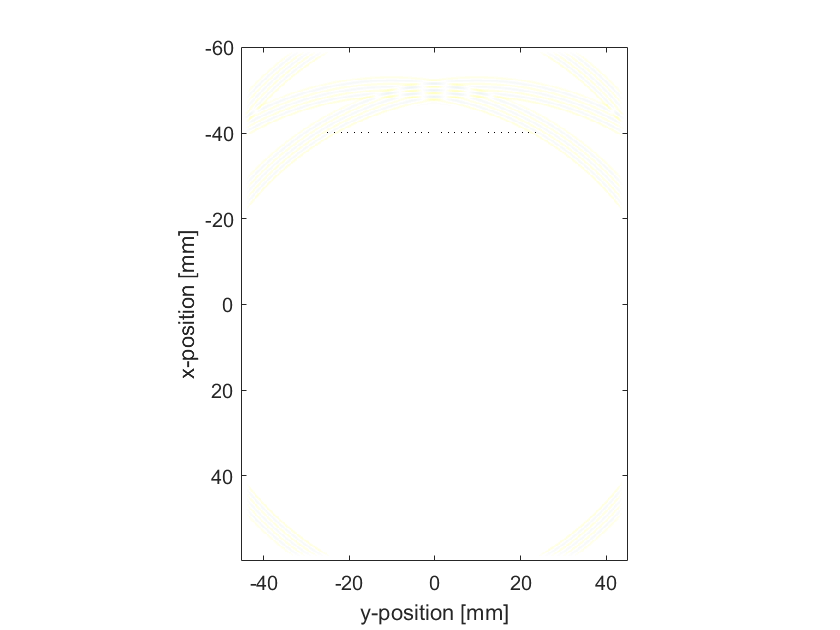

  simulation completed in 50.7784s
  total computation time 50.89s


% run the simulation
sensor_data = kspaceFirstOrder2D(Kgrid, medium, source, sensor);

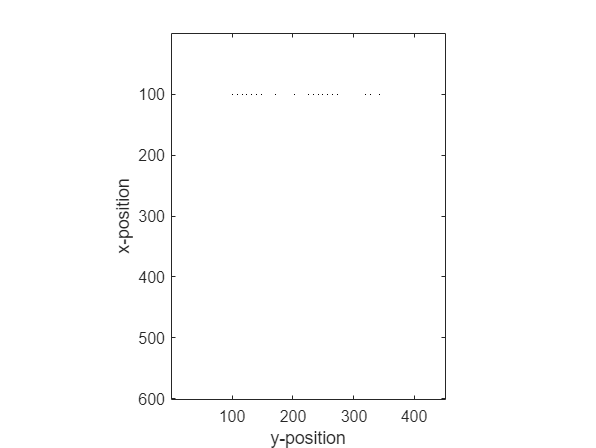

% VISUALISATION
% =========================================================================

% plot the initial pressure and sensor distribution
%positive max around 0.043-0.0449
figure;
%imagesc(Kgrid.y_vec * 1e3, Kgrid.x_vec * 1e3, source.p0 + cart2grid(Kgrid, sensor.mask), [-1, 1]);
imagesc(source.p_mask + sensor.mask, [-1, 1]);
%imagesc(source.p0 + sensor.mask, [-1, 1]);
colormap(getColorMap);
ylabel('x-position');
xlabel('y-position');
axis image;

%% 


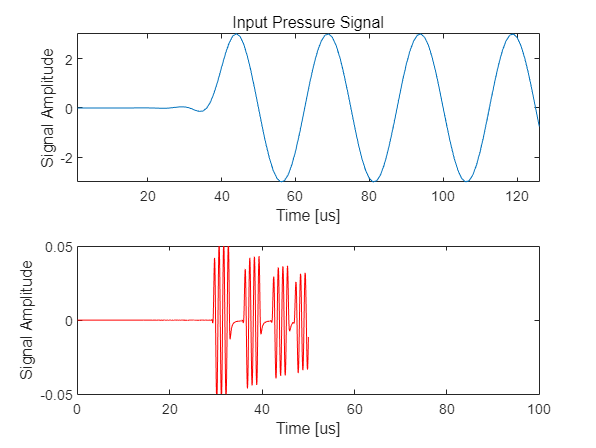



% plot the simulated sensor data
figure;
[t_sc, scale, prefix] = scaleSI(max(t_array_new));

subplot(2, 1, 1);
plot(source.p)
%plot(t_array_new * scale, source.p, 'k-');
xlabel(['Time [' prefix 's]']);
ylabel('Signal Amplitude');
axis ([-inf,inf,-inf,inf]);
title('Input Pressure Signal');

subplot(2, 1, 2);
plot(Kgrid.t_array * scale, sensor_data(32,:), 'r-');
xlabel(['Time [' prefix 's]']);
ylabel('Signal Amplitude');
axis ([0,100,-0.05,0.05]);

%axis tight;
%axis([0,10.5,-inf,inf]);



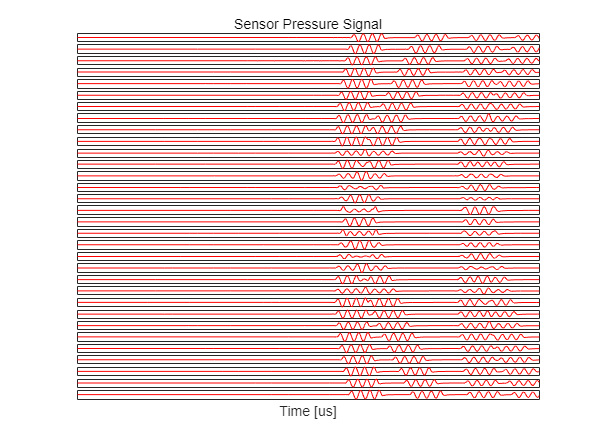

%plot all the 32 original sensor signal 
figure
for i = 1:32
    subplot(32, 1, i);
    plot(Kgrid.t_array * scale, sensor_data(i,:), 'r-');

    %axis([0,10.5,-inf,inf]);
    set(gca,'XTick',[],'YTick',[]);
    if i == 1
            %xlabel(['Time [' prefix 's]']);
            ylabel('Signal Amplitude');
            title('Sensor Pressure Signal');
    end
    if i == 32 
        xlabel(['Time [' prefix 's]']);
        %ylabel('Signal Amplitude');
        %title('Sensor Pressure Signal');
    end

end

%% dt=40ns tend=100.04us timestep = 2502 totalt=1e-4




%obtian all the sensor position
sensorpoistion = zeros(1,32)

sensorpoistion =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j=1

j = 1

for i = 1:450
    if sensor.mask(100,i)==1
        
        sensorpoistion(j) = i;
        j = j+1;
    end
end
sensorpoistion()

ans =    101   109   117   124   132   140   148   156   164   171   179   187   195   203   210   218   226   234   242   249   257   265   273   281   289   296   304   312   320   328   335   343


%distance from sensor to source mm
distance_map = zeros(1,32);
intensitymap = zeros(1,1600);
%sourceposition =[70/120*Nx, Ny/2]%x=350,y=225
distance = zeros(1,32);
for i = 1:32
    distance(i) = sqrt((sensorpoistion(i)-225)^2+(350-100)^2);
end


%all the source position

%Create a 20mm times 20mm grid, which is 200 times 200
%x from 
map_length = zeros(1,200);
map_width = zeros(1,200);
%x_offset, Ny/2 - width/2 + 1:7.8125:Ny/2 + width/2

for i = 1:200
    map_length(i)=350-Nx/6+i;
    map_width(i)=225-20/90*Ny+i;
end
map_length

map_length =    251   252   253   254   255   256   257   258   259   260   261   262   263   264   265   266   267   268   269   270   271   272   273   274   275   276   277   278   279   280   281   282   283   284   285   286   287   288   289   290   291   292   293   294   295   296   297   298   299   300


map_width

map_width =    126   127   128   129   130   131   132   133   134   135   136   137   138   139   140   141   142   143   144   145   146   147   148   149   150   151   152   153   154   155   156   157   158   159   160   161   162   163   164   165   166   167   168   169   170   171   172   173   174   175


%x = 350-map_width:350+map_width
%y = 225-map_width:225+map_width


%the intensity map position
%map_width = 40/120*Nx;
%map = zeros(map_width,map_width);

%store the map postion
step = zeros(1,32)

step =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


sensor_data_test = zeros(32,1251);
sensor_data_new = zeros(32,1251);
coeff = 4/32*pi;
%times distance with the sensor data3m
A = zeros(32,1251)

A =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   

%define the energy map
energymap = zeros(200,200)

energymap =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0 


%ATP extract time window
% source_signal = source_mag * sin(2 * pi * source_freq * t_array_new);
% figure
% plot(t_array_new * scale, source_signal, 'r-');
% xlabel(['Time [' prefix 's]']);
% ylabel('Source strength');
% tend = 5.2e-6;
% tstart = 1e-6;
timewindow = t_array_new(26:126)

timewindow = 1.0e-05 *

    0.1000    0.1040    0.1080    0.1120    0.1160    0.1200    0.1240    0.1280    0.1320    0.1360    0.1400    0.1440    0.1480    0.1520    0.1560    0.1600    0.1640    0.1680    0.1720    0.1760    0.1800    0.1840    0.1880    0.1920    0.1960    0.2000    0.2040    0.2080    0.2120    0.2160    0.2200    0.2240    0.2280    0.2320    0.2360    0.2400    0.2440    0.2480    0.2520    0.2560    0.2600    0.2640    0.2680    0.2720    0.2760    0.2800    0.2840    0.2880    0.2920    0.2960


sensor_timewindow = zeros(32,101)

sensor_timewindow =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     




sensorpoistion

sensorpoistion =    101   109   117   124   132   140   148   156   164   171   179   187   195   203   210   218   226   234   242   249   257   265   273   281   289   296   304   312   320   328   335   343


for m = 1:200
     for n = 1:200
         A = zeros(32,101);
        for i = 1:32
            %calculate distance from each point
            distance_map(1,i)=sqrt((sensorpoistion(i)-map_width(m))^2+(map_length(n)-100)^2);
            timeshift = distance_map*dx/c;

            
            %apply the time delay to the sensor data
            step(i) = floor(timeshift(i)/4e-8);
            sensor_data_test(i,:) = sensor_data(i,:);
            sensor_data_new(i,:) = circshift(sensor_data_test(i,:), -step(i));
            sensor_timewindow(i,:) = sensor_data_new(i,26:126);
            A(i,:) = distance_map(i)*sensor_timewindow(i,:);
        end
        %sum 32 sensor data together
        
        sum_A = sum(A);
        intensity = coeff * sum_A;

        %integral'
        intensity_2 = intensity.^2;
        Q = trapz(intensity_2);
        coeff2 = 1/(4*pi*1500);
        energymap(n,m)= Q*coeff2;
     end
end


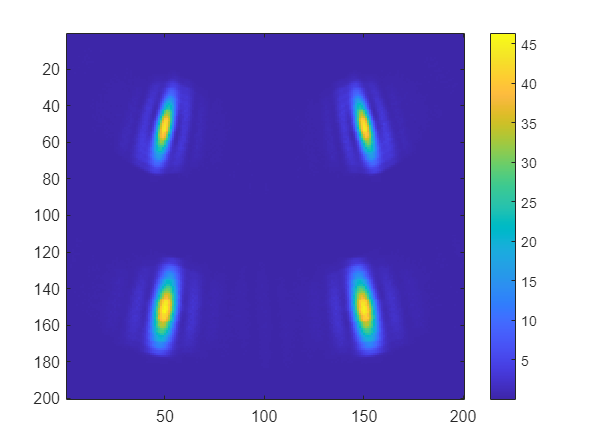

figure

%imshow(energymap/256)

%imshow(uint8(energymap))
imagesc(energymap);
colorbar;  % colorbar 的作用是生成一个代表颜色值的条状图例

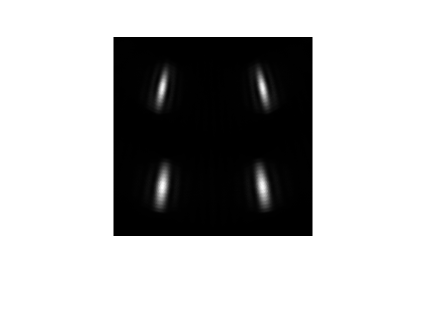

rea = im2uint8(mat2gray(energymap));
figure
imshow(rea)


% step
% timeshift
% distance_map
% for m = 1:200
%     for n = 1:200
%         i
%         for i = 1:32
%             %calculate distance from each point
%             distance_map(1,i)=sqrt((sensorpoistion(i)-map_width(n))^2+(map_length(m)-100)^2);
%             timeshift = distance_map*dx/c;
% 
%             
%             %apply the time delay to the sensor data
% %             step(i) = floor(tj(i)/4e-8);
% %             sensor_data_test(i,:) = sensor_data(i,:);
% %             sensor_data_new(i,:) = circshift(sensor_data_test(i,:), -step(i));

%         end
%     end
% end

%source strength = 4pi/N*sum(distance*signal)

coeff = 4/32*pi

coeff = 0.3927

%distance_total = sum(distance, 'all')


%Shift test
%1st calculate how much time step to move
% step = tj(1)/4e-8%how many step to move
% step = floor(step)
% sensor_data_test = sensor_data(1,:)
% sensor_data_new = circshift(sensor_data_test, -step)

%shift test2
% function [AfterArray] = ArrayDisplacement(BeforeArray,direction,len,type)
% ArrayEnd = length(BeforeArray);
% eforeArrayL = BeforeArray(1:len);
% BeforeArrayR = BeforeArray(len+1:ArrayEnd);
% BeforeArrayL = fliplr(BeforeArrayL);
% BeforeArrayR = fliplr(BeforeArrayR);
% BeforeArray = [BeforeArrayL BeforeArrayR];
% AfterArray = fliplr(BeforeArray);

%apply the time delay to the sensor data
step = zeros(1,32)

step =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


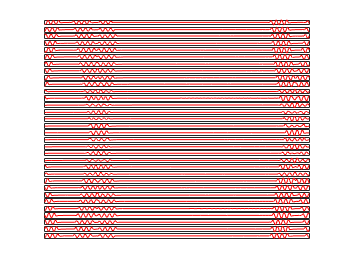

sensor_data_test = zeros(32,1251);
sensor_data_new = zeros(32,1251);
tj = distance*dx/c;
for i = 1:32
    step(i) = floor(tj(i)/4e-8);
    sensor_data_test(i,:) = sensor_data(i,:);
    sensor_data_new(i,:) = circshift(sensor_data_test(i,:), -step(i));
    %plot the shifted data 
    subplot(32, 1, i);
    plot(Kgrid.t_array * scale, sensor_data_new(i,:), 'r-');
    set(gca,'XTick',[],'YTick',[]);
    %axis([0,10.5,-inf,inf]);
end

%ATP extract time window
% source_signal = source_mag * sin(2 * pi * source_freq * t_array_new);
% figure
% plot(t_array_new * scale, source_signal, 'r-');
% xlabel(['Time [' prefix 's]']);
% ylabel('Source strength');
% tend = 5.2e-6;
% tstart = 1e-6;

%timewindow = t_array_new(26:126)

sensor_timewindow = sensor_data_new(:,26:126)

sensor_timewindow =    -0.0303   -0.0371   -0.0416   -0.0435   -0.0428   -0.0394   -0.0335   -0.0257   -0.0162   -0.0058    0.0049    0.0153    0.0247    0.0325    0.0382    0.0415    0.0421    0.0401    0.0355    0.0286    0.0199    0.0099   -0.0007   -0.0113   -0.0213   -0.0299   -0.0367   -0.0412   -0.0432   -0.0424   -0.0390   -0.0332   -0.0254   -0.0160   -0.0056    0.0052    0.0156    0.0249    0.0326    0.0383    0.0417    0.0425    0.0404    0.0352    0.0275    0.0186    0.0099    0.0024   -0.0031   -0.0067
   -0.0390   -0.0325   -0.0241   -0.0142   -0.0034    0.0075    0.0179    0.0272    0.0346    0.0399    0.0427    0.0427    0.0400    0.0347    0.0273    0.0181    0.0077   -0.0032   -0.0140   -0.0238   -0.0322   -0.0386   -0.0427   -0.0441   -0.0427   -0.0386   -0.0322   -0.0238   -0.0139   -0.0032    0.0078    0.0182    0.0274    0.0348    0.0400    0.0429    0.0431    0.0402    0.0343    0.0261    0.0168    0.0080    0.0008   -0.0044   -0.0076   -0.0092   -0.0096   -0.009

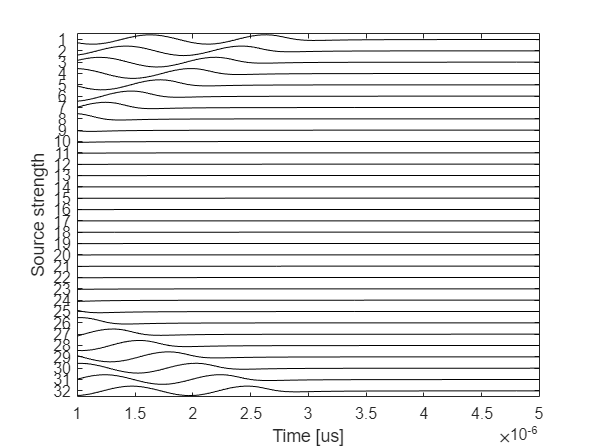

figure
stackedPlot(timewindow, sensor_timewindow);
xlabel(['Time [' prefix 's]']);
ylabel('Source strength');

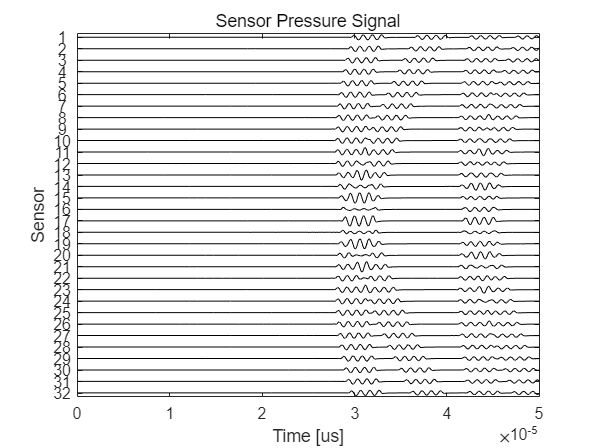

figure

stackedPlot(Kgrid.t_array,sensor_data)
ylabel('Sensor');
xlabel(['Time [' prefix 's]']);
title('Sensor Pressure Signal');

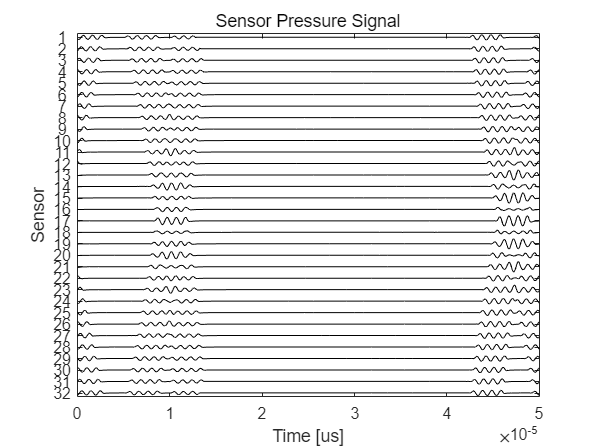


figure
stackedPlot(Kgrid.t_array,sensor_data_new)
ylabel('Sensor');
xlabel(['Time [' prefix 's]']);
title('Sensor Pressure Signal');

%calculate intensity
figure
A = zeros(32,1251)

A =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   

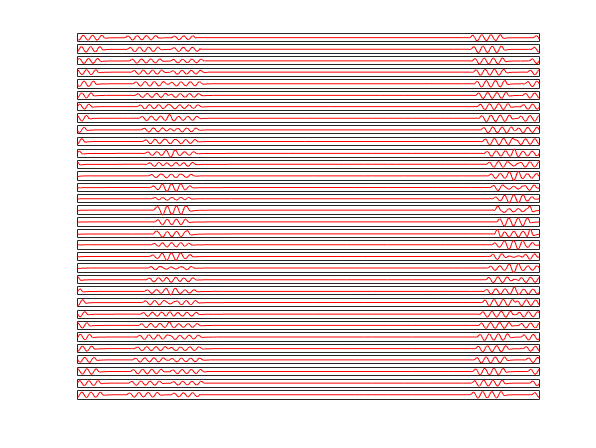

A(1,:) = distance(1)*sensor_data_new(1,:);
for i = 1:32
    A(i,:) = distance(i)*sensor_data_new(i,:);
    subplot(32, 1, i);
    plot(Kgrid.t_array * scale, A(i,:), 'r-');
    set(gca,'XTick',[],'YTick',[]);
end

figure
sum_A = sum(A)

sum_A =   -22.0950  -17.9030  -13.2251   -8.7208   -4.6289   -0.7758    3.0956    6.9573   10.3941   12.8505   14.0104   13.9853   13.1520   11.7907    9.8479    7.0348    3.1765   -1.4983   -6.3849  -10.8200  -14.4116  -17.1018  -18.9426  -19.8300  -19.4723  -17.6311  -14.4011  -10.2470   -5.7419   -1.2349    3.2536    7.8111   12.2899   16.1604   18.7150   19.4706   18.4399   16.0513   12.8013    8.9562    4.5621   -0.2797   -5.1811   -9.5462  -12.9088  -15.1929  -16.6238  -17.3708  -17.2915  -16.0522



%plot(Kgrid.t_array * scale, sum_A, 'r-');
intensity = coeff * sum_A

intensity =    -8.6767   -7.0305   -5.1935   -3.4247   -1.8178   -0.3047    1.2156    2.7321    4.0818    5.0464    5.5019    5.4920    5.1648    4.6302    3.8673    2.7626    1.2474   -0.5884   -2.5073   -4.2490   -5.6594   -6.7159   -7.4387   -7.7872   -7.6467   -6.9237   -5.6553   -4.0240   -2.2549   -0.4849    1.2777    3.0674    4.8262    6.3462    7.3494    7.6461    7.2413    6.3033    5.0271    3.5171    1.7915   -0.1098   -2.0346   -3.7488   -5.0693   -5.9662   -6.5282   -6.8215   -6.7903   -6.3037


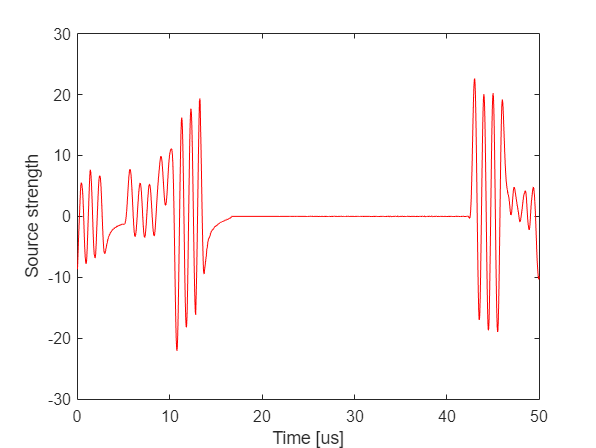

plot(Kgrid.t_array * scale, intensity, 'r-');
xlabel(['Time [' prefix 's]']);
ylabel('Source strength');

%integral'
intensity_2 = intensity.^2;
Q = trapz(intensity_2)

Q = 3.9162e+04

coeff2 = 1/(4*pi*1500)

coeff2 = 5.3052e-05

%fun = @(x) exp(-x.^2).*log(x).^2;
fun = @(x) (coeff2*sum(A)).^2

fun = 包含以下值的 function_handle :
    @(x)(coeff2*sum(A)).^2


%fun_2 = fun.^2
q = integral(fun,0,5e-05,'ArrayValued',true)

q = 1.0e-09 *

    0.0687    0.0451    0.0246    0.0107    0.0030    0.0001    0.0013    0.0068    0.0152    0.0232    0.0276    0.0275    0.0243    0.0196    0.0136    0.0070    0.0014    0.0003    0.0057    0.0165    0.0292    0.0412    0.0505    0.0553    0.0534    0.0437    0.0292    0.0148    0.0046    0.0002    0.0015    0.0086    0.0213    0.0368    0.0493    0.0533    0.0479    0.0363    0.0231    0.0113    0.0029    0.0000    0.0038    0.0128    0.0234    0.0325    0.0389    0.0425    0.0421    0.0363


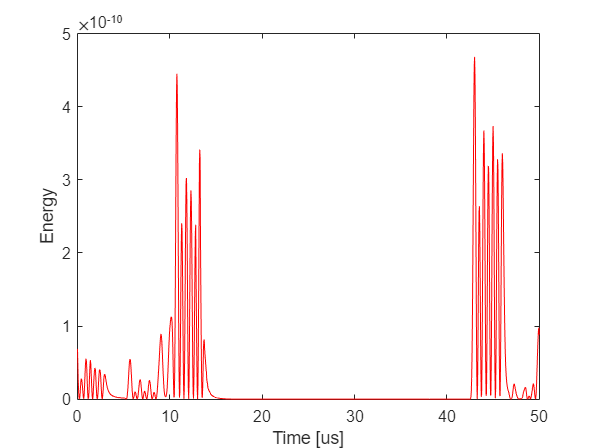

figure
plot(Kgrid.t_array * scale, q, 'r-');
xlabel(['Time [' prefix 's]']);
ylabel('Energy');


%original received signal
step(1)

ans = 930

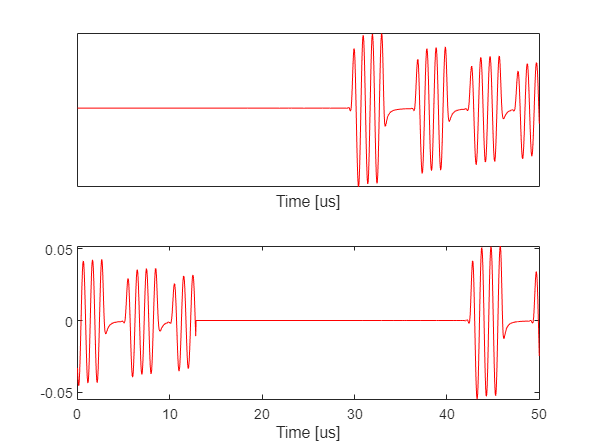

%sensor_data_new(1,:) = circshift(sensor_data_test(1,:), -step);
figure
subplot(2,1,1);
plot(Kgrid.t_array * scale, sensor_data_test(1,:), 'r-');
set(gca,'XTick',[],'YTick',[]);
xlabel(['Time [' prefix 's]']);
%shifted signal
subplot(2,1,2);
plot(Kgrid.t_array * scale, sensor_data_new(1,:), 'r-');
xlabel(['Time [' prefix 's]']);


% sensor_data_new = distance * sensor_data
% figure
% subplot(2,1,1);
% plot(Kgrid.t_array * scale, sensor_data_new, 'r-');
% subplot(2,1,2);
% plot(Kgrid.t_array * scale, sensor_data(31,:), 'r-');



无法识别的字段名称 "setCustomWaveform"。

help kWaveGrid

 kWaveGrid Class definition for k-Wave grid.
 
  DESCRIPTION:
      kWaveGrid is the grid class used across the k-Wave Toolbox. An object
      of the kWaveGrid class contains the grid coordinates and wavenumber
      matrices used within the simulation and reconstruction functions in
      k-Wave. The grid matrices are indexed as: (x, 1) in 1D; (x, y) in
      2D; and (x, y, z) in 3D. The grid is assumed to be a regularly spaced
      Cartesian grid, with grid spacing given by dx, dy, dz (typically the
      grid spacing in each direction is constant). 
 
  USAGE:
      kgrid = kWaveGrid(Nx, dx)
      kgrid = kWaveGrid(Nx, dx, Ny, dy)
      kgrid = kWaveGrid(Nx, dx, Ny, dy, Nz, dz)
 
  INPUTS:
      Nx, Ny, Nz      - number of grid points in each Cartesian direction
      dx, dy, dz      - grid point spacing in each Cartesian direction [m]
 
  OUTPUTS:
      kgrid           - 